Дана функция x(t)=(t^2-t)(2t+1) в пространстве L2(-1;1) со скалярным произведением. 

Инициализируем перемнные:

syms t;
x_t=(t^2-t)*(2*t+1);
P = cell(1, 3);
P{1} = 1 / sqrt(2);
P{2} = sqrt(3/2) * t;
P{3} = sqrt(5/2) * ((3 * t^2) / 2 - 1/2);
c = sym(zeros(1, 3));%для хранения коэффицентов Фурье
s = cell(1, 2); % для хранения наилучших приближений
summa=sym(0);

Вычисляем коэффиценты Фурье:

for k = 1:3
    c(k) = int(x_t * P{k}, t, -1, 1);
end
disp(c);

$$\left(\begin{array}{ccc} -\frac{\sqrt{2}}{3} & \frac{\sqrt{6}}{15} & -\frac{2\,\sqrt{10}}{15} \end{array}\right)$$

Вычисляем наилучшие приближения первого и второго порядков:

for m = 1:3 
    summa = summa + c(m) * P{m};
    if m>1
        s{m-1} = simplify(summa);
    end
end

Графики

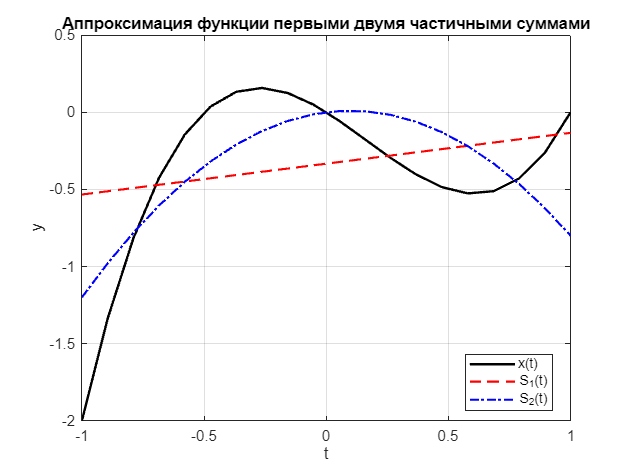

tt  = linspace(-1, 1, 20);
f_vals  = double( subs(x_t, t, tt) );
S1_vals = double( subs( s{1}, t, tt) );    % s{1} – первое приближение
S2_vals = double( subs( s{2}, t, tt) );    % s{2} – второе приближение
plot(tt, f_vals , 'k-', 'LineWidth', 1.6); hold on
plot(tt, S1_vals, 'r--','LineWidth', 1.4);          
plot(tt, S2_vals, 'b-.','LineWidth', 1.4); hold off 

legend('x(t)', 'S_1(t)', 'S_2(t)', 'Location', 'best');
xlabel('t'); ylabel('y');
title('Аппроксимация функции первыми двумя частичными суммами');
grid on

Ответ:

disp(s);

    {[t/5 - 1/3]}    {[-(t*(5*t - 1))/5]}

